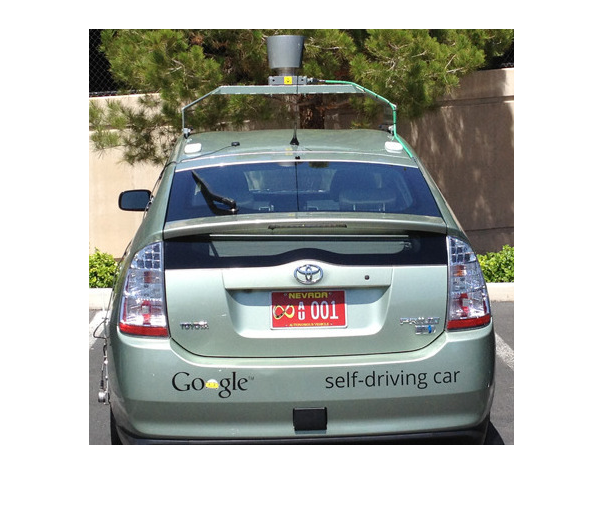

% Author: Shaqueir Tardif
clear;

% Define encyrption variables
secretKey='5b0efc93842eca9a89eb5d652018d5713d02a5881be9241be29b8e80c9db4a4e';
iv='6a75d6d0bc29918ffe1fc1c1';

% Load image
img1_org = imread("test_image3.jpeg");
img_new = img1_org;
imshow(img1_org)


timer = tic();

% Identifies all red pixels where red value far exeeds red and blue value
% and set them to 0
not_red = and(img1_org(:, :, 1) - img1_org(:, :, 2) < 200, (img1_org(:, :, 1) - img1_org(:, :, 3) < 200));

% finds all 0 in logical array notred
[red_posys, red_posxs] = find(not_red == 0);
min_red_posy = min(red_posys);
max_red_posy = max(red_posys);
min_red_posx = min(red_posxs);
max_red_posx = max(red_posxs);
mean_red_posy = round(mean([min_red_posy, max_red_posy])) ;
mean_red_posx = round(mean([min_red_posx,max_red_posx]));


% Mark location of red ball
buffer = 0;
offset = 50

offset = 50

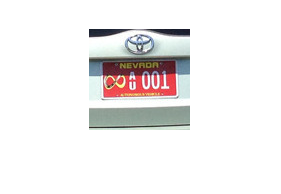

%round(max(abs(mean_red_posx - min_red_posx), abs(mean_red_posy - min_red_posy)) + buffer)
img1_cut = img1_org(mean_red_posy - offset: mean_red_posy + offset, mean_red_posx - offset: mean_red_posx + offset, :);
imshow(img1_cut)

%Encryption
[img1_cut,authTag]=ImageEncryption(secretKey, iv, img1_cut, 'AES image');
img_new(mean_red_posy - offset: mean_red_posy + offset, mean_red_posx - offset: mean_red_posx + offset,:) = img1_cut(:, :, :);
toc(timer)

Elapsed time is 17.582244 seconds.


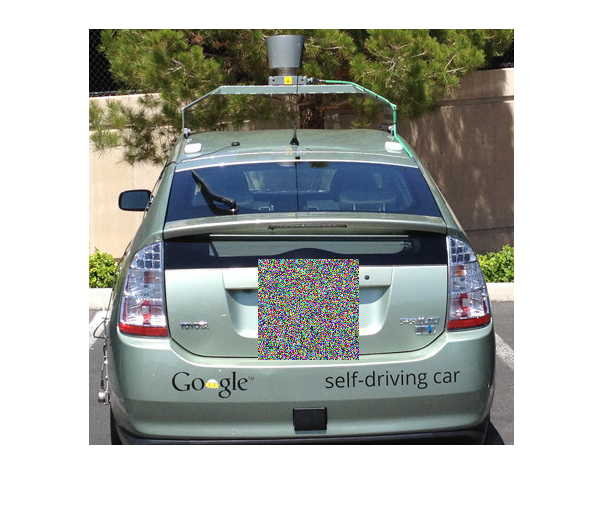

imshow(img_new)


%Encryption
timer = tic();
[img1_new,authTag2]=ImageEncryption(secretKey, iv, img1_org, 'AES image');
toc(timer)

Elapsed time is 360.606151 seconds.


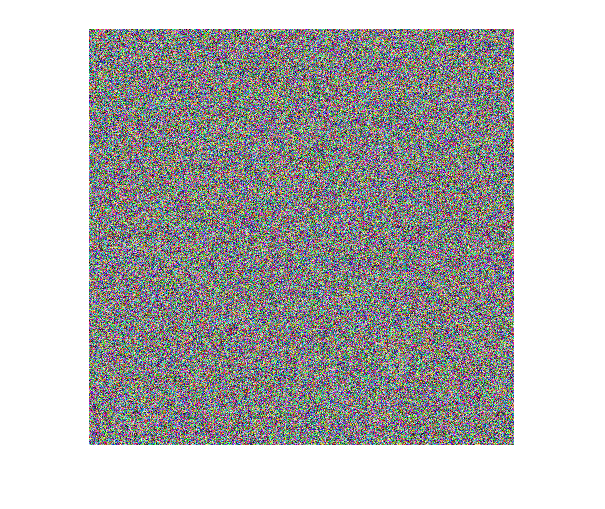

imshow(img1_new)


%Decryption
img1_cut_dec = img1_org(mean_red_posy - offset: mean_red_posy + offset, mean_red_posx - offset: mean_red_posx + offset, :);
imshow(img1_cut_dec)

[img1_cut_dec,authTagResult]=ImageDecryption(secretKey, iv, img1_cut, 'AES image', authTag);

img_dec(mean_red_posy - offset: mean_red_posy + offset, mean_red_posx - offset: mean_red_posx + offset,:) = img1_cut_dec(:, :, :);
timer = tic();
toc(timer)

Elapsed time is 0.001589 seconds.


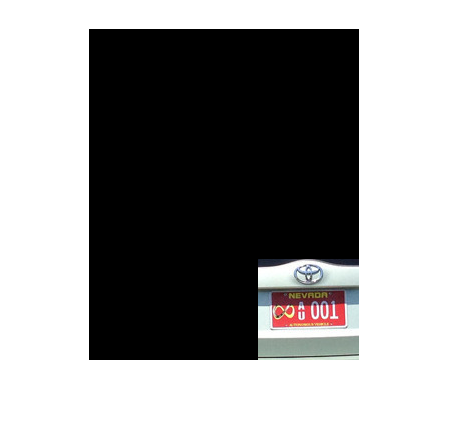

imshow(img_dec)


%Decryption
timer = tic();
[img1_dec,authTag2Result]=ImageDecryption(secretKey, iv, img1_new, 'AES image', authTag2);

toc(timer)

Elapsed time is 365.464978 seconds.


imshow(img1_dec)